clc; clear

%defining parameters  
syms u t %making variables symbolic for equations 
d = 0.245; %wheelbase
beta = .12; %for u(t) - keeps the velocities under 0.3m/s (anything above 0.3m/s gives errors) 
assume(0 <= u <= 3.2) %restricts range of values 
u = beta * t; % u(t)

%paramtric equations 
X = 0.396 * cos(2.65 * (u+1.4));
Y = -0.99 * sin(u + 1.4);
Z = 0; %third component to be able to take the cross product for w 
r = [X; Y; Z];

%computing linear velocity - change in theta(u) over time (t) 
derivative_rt = diff(r, t); %r'(t) or velocity 
linear_speed = norm(derivative_rt); %|r'(t)|

%computing tangent vector  
Tangent = derivative_rt ./ linear_speed;
Tangent_new = simplify(Tangent); 

%# of timesteps  
t1 = 100; 

%establishing time variable  
time = linspace(0,3.2/beta, t1);

%determining w in velocity equation - angular velocity 
w = cross(Tangent_new, diff(Tangent_new, t)); 

%establishing variables for linear and angular velocity 
t_linear_velocity = zeros(1,t1);
angle_velocity = zeros(1,t1); 

%finding linear and angular velocity over time
for j = 1:t1
t_linear_velocity(1,j) = subs(linear_speed, t, time(1,j));
angle_velocity(1,j) = subs(w(3), t, time(1,j)); 
end

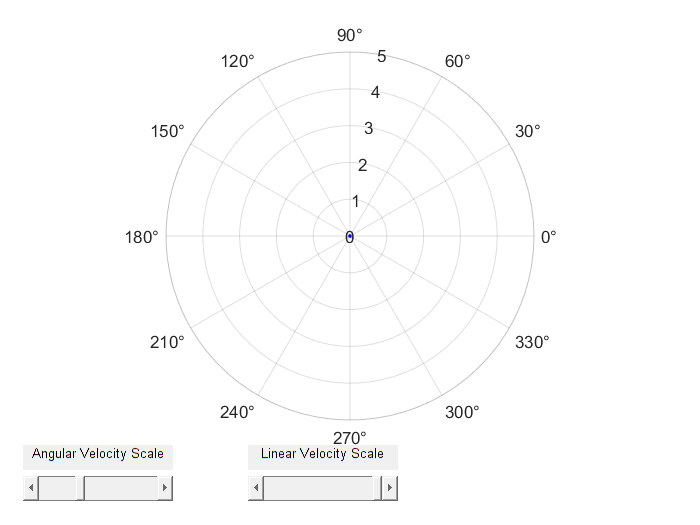

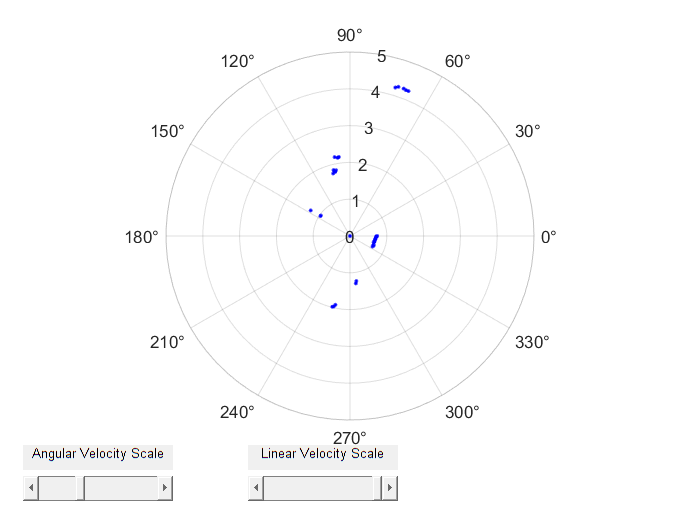

% test
close all;
%[sensors,vels]=neatoSim();
[sensors,vels]=neato('192.168.16.100'); %uncomment for physical neato
%pause(10) %wait a bit for the robot to start up

drdt(t)=diff(r,t);
drivetime = 3.2/beta; 
i = 1;
lv_hold = zeros(1,100);
rv_hold = zeros(1,100);
iter = 0;
max_points = 3000; 
encoder_data=zeros(max_points,3);

time_stamp = zeros(1,448); 
tic %start your timer in Matlab
times=toc; %t updates as the time since you started
while times<drivetime 
    iter = iter+1; 
    velocity = double(norm(drdt(times)));
    left_velocity = velocity - (w(3) * (d/2));
    right_velocity = velocity + (w(3) * (d/2)); 
    lv = double(subs(left_velocity, t, times));
    rv = double(subs(right_velocity, t, times)); 
    if iter <= max_points
        if time <= drivetime
        lv_hold(1,i) = lv;
        rv_hold(1,i) = rv;
        time_stamp (1,i) = times; 
        i = i+1; 
            if size(sensors.encoders) > 0
                encoder_data(iter,:)=[times,sensors.encoders(1),sensors.encoders(2)];
            end
        end
    end 
    vels.lrWheelVelocitiesInMetersPerSecond=[double(subs(left_velocity, t, times)), double(subs(right_velocity, t, times))]; 
    times=toc; %t updates as the time since you started
end

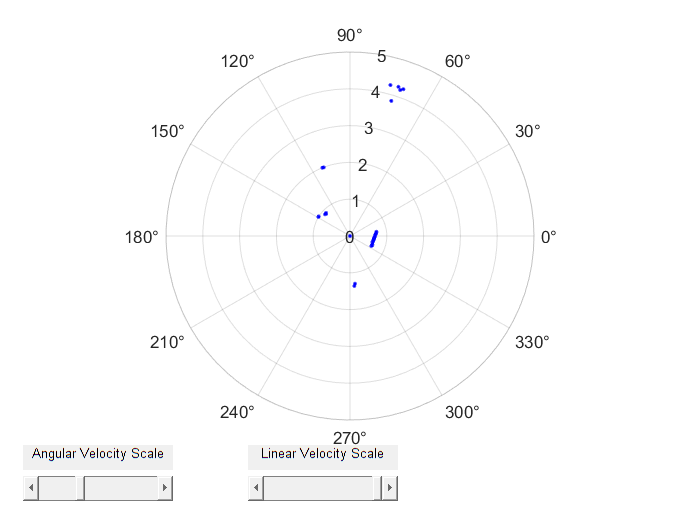

encoder_data=encoder_data(1:iter,:);
vels.lrWheelVelocitiesInMetersPerSecond=[0,0];
pause(1);

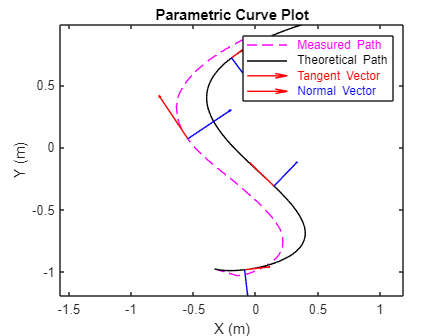

% Plot encoder data
% row 1 is time, 2 is left wheel, 3 is right wheel
hold off;
figure;
scatter(encoder_data(:,1),encoder_data(:,2:3));
xlabel("Time (s)")
ylabel("Linear Travel (m)")

left_vel = diff(encoder_data(:,2)) ./ diff(encoder_data(:, 1));
right_vel = diff(encoder_data(:,3)) ./ diff(encoder_data(:, 1));
left_vel(size(left_vel)+1) = 0;
right_vel(size(right_vel)+1) = 0;


%Plot wheel velocities 
hold off;
figure;
plot(encoder_data(:, 1), left_vel, '--', 'color','r'); hold on
plot(encoder_data(:, 1), right_vel, '--','color','b');

row = length(encoder_data);
rv_hold = rv_hold(1,1:row);
lv_hold = lv_hold(1,1:row);

plot(encoder_data(:, 1),rv_hold,'color','b'); hold on; 
plot(encoder_data(:, 1), lv_hold,'color','r'); 
xlabel('Time (s)');
ylabel('Wheel velocity (m/s)');
title('Wheel Velocities');
legend('Measured left wheel velocity', 'Measured right wheel velocity', 'Predicted Right wheel velocity', ' Predicted Left wheel velocity');
hold off;


%Plot angular velocities
omega_measured = (right_vel - left_vel)./d;
omega_measured = omega_measured(1:row,1);
angle_velocity = angle_velocity(1,1:row);

figure;
plot(encoder_data(:, 1), omega_measured, '--', 'color', 'r'); hold on;
plot(encoder_data(:,1), angle_velocity, 'b');
xlabel("Time (s)")
ylabel("Angular Velocity (radians/s)")
legend('Measured angular velocity', 'Theoretical angular velocity');
title('Angular Velocities');
hold off;

%Plot parametric curve path with normal and tangent vectors
V_measured = (left_vel + right_vel) ./ 2;
values = isnan(V_measured);

for q = 1:length(V_measured)
if values(q,1) == 1
    V_measured(q,1) = 0;
end
end

values_o = isnan(omega_measured);
for e = 1:length(omega_measured)
if values_o(e,1) == 1
    omega_measured(e,1) = 0; 
end
end

timestep = diff(encoder_data(:, 1));
robot_pos = zeros(length(timestep), 3);

r = 0; 
X_1 = 0.396 * cos(2.65 * (r + 1.4));
Y_1 = -0.99 * sin(r + 1.4);

robot_pos(1, 1) = X_1;
robot_pos(1, 2) = Y_1;
theta_naught = double(subs(Tangent_new,t,0));
robot_pos(1, 3) = atan(theta_naught(2,1) / theta_naught(1,1));

for b = 2:length(timestep)
    robot_pos(b, 1) = robot_pos(b-1, 1) + (V_measured(b-1,1) * cos(robot_pos(b-1, 3)) * timestep(b-1,1));
    robot_pos(b, 2) = robot_pos(b-1, 2) + (V_measured(b-1,1) * sin(robot_pos(b-1, 3)) * timestep(b-1,1));
    robot_pos(b, 3) = robot_pos(b-1, 3) + (omega_measured(b-1,1) * timestep(b-1,1));
end

figure;
plot(robot_pos(:, 1), robot_pos(: , 2), '--', 'color', 'm'); hold on; 
xlabel("X (m)")
ylabel("Y (m)")
title("Parametric Curve Plot")
axis equal

p = linspace(0,3.2);
X_o = 0.396*cos(2.65*(p+1.4)); %have to add it beta value 
Y_o = -0.99*sin(p+1.4);
Xder = -0.396*sin(2.65*(p+1.4))*2.65;
Yder = -0.99*cos(p+1.4); 
plot(X_o,Y_o, 'color', 'k'); 
Q1 = quiver(X_o(10), Y_o(10), Xder(10), Yder(10), 0.2, 'r'); 
quiver(X_o(45), Y_o(45), Xder(45), Yder(45), 0.2, 'r');
quiver(X_o(80), Y_o(80), Xder(80), Yder(80), 0.2, 'r');
Q2 = quiver(X_o(10), Y_o(10), Yder(10), -Xder(10), 0.2, 'b'); 
quiver(X_o(45), Y_o(45), Yder(45), -Xder(45), 0.2, 'b');
quiver(X_o(80), Y_o(80), Yder(80), -Xder(80), 0.2, 'b');
axis equal

robot_pos_xder = diff(robot_pos(:, 1));
robot_pos_yder = diff(robot_pos(:, 2));

quiver(robot_pos(20,1), robot_pos(20,2), robot_pos_xder(20,1), robot_pos_yder(20,1), 10, 'r');
quiver(robot_pos(60,1), robot_pos(60,2), robot_pos_xder(60,1), robot_pos_yder(60,1), 10, 'r');
quiver(robot_pos(70,1), robot_pos(70,2), robot_pos_xder(70,1), robot_pos_yder(70,1), 10, 'r');
quiver(robot_pos(20,1), robot_pos(20,2), robot_pos_yder(20,1), -robot_pos_xder(20,1), 10, 'b');
quiver(robot_pos(60,1), robot_pos(60,2), robot_pos_yder(60,1), -robot_pos_xder(60,1), 10, 'b');
quiver(robot_pos(70,1), robot_pos(70,2), robot_pos_yder(70,1), -robot_pos_xder(70,1), 10, 'b');

legend('\color{magenta} Measured Path','\color{black} Theoretical Path','\color{red} Tangent Vector','\color{blue} Normal Vector');


%Plotting linear speed 
linear_speed_updated = double(subs(linear_speed,t,encoder_data(:, 1))); 
plot(encoder_data(:, 1), V_measured);hold on; 
plot(encoder_data(:, 1), linear_speed_updated); 
legend('Measured Linear Speed', 'Theoretical Linear Speed'); 
title('Linear Speed'); 
xlabel('Time (s)');
ylabel('Speed (m/s)'); 